# 光学观测定轨

## 1.题目

已知某测站的位置为：经度24.583º，纬度5.866º，高程0m。对某一地球卫星进行观测，得到的高低角、方位角以及距离的数据如下表所示。观测时，高低角、方位角及距离均带有噪声。地球赤道半径为6378.140km，偏心率0.081 819。

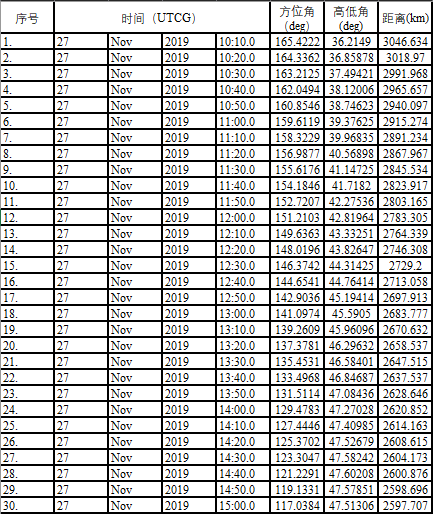

1.1 试仅利用角度观测数据，采用拉普拉斯方法和高斯方法确定卫星的轨道根数，并分析结果间的差异。

1.2 试采用距离观测数据，改进卫星轨道确定的精度。

## 2.求解

### 2.1 数据导入

clear;
lambda = 24.583; %longitude，经度
latitude = 5.866;
altitude = 0;
data = xlsread('data.xlsx');
azimuth = data(:,5);
elevation = data(:,6);
distance = data(:,7)*1000; %注意单位转换

由于读入的小时-分钟-秒数据被自动转为小数，以及月份读到的是NaN，因此需要做一步处理。

UTC=datetime(2019,11,27,floor(data(:,4)*24),floor(data(:,4)*24*60)-floor(data(:,4)*24)*60,floor(data(:,4)*24*3600-floor(data(:,4)*24)*3600-(floor(data(:,4)*24*60)-floor(data(:,4)*24)*60)*60));

### 2.2 求当地真恒星时

timesystem = timeSystem.TimeSystem(UTC,lambda)

timesystem =   TimeSystem with properties:

        UTC: [30×1 datetime]
    lambdaG: 24.5830
     lambda: 24.5830
        TAI: [30×1 datetime]
         TT: [30×1 datetime]
        TDT: [30×1 datetime]
         ET: [30×1 datetime]
        UT1: [30×1 datetime]
      Smean: [30×1 double]
          S: [30×1 double]
      smean: [30×1 double]
          s: [30×1 double]


### 2.3 观测数据预处理

观测数据预处理，由于该Preprocessing需要输入变化率，因此置变化率为零

Dazimuth = zeros(length(data(:,1)),1);
Delevation = zeros(length(data(:,1)),1);
Ddistance = zeros(length(data(:,1)),1);
preprocessing = orbitDefine.Preprocessing(latitude,timesystem.s/3600*15,altitude,azimuth,elevation,distance,Dazimuth,Delevation,Ddistance)

preprocessing =   Preprocessing with properties:

        Glatitude: 5.8660
                s: [30×1 double]
         altitude: 0
          azimuth: [30×1 double]
        elevation: [30×1 double]
         distance: [30×1 double]
         Dazimuth: [30×1 double]
       Delevation: [30×1 double]
        Ddistance: [30×1 double]
       stationPos: [30×3 double]
    spacecraftDir: [30×3 double]
    spacecraftPos: [30×3 double]
    spacecraftVel: [30×3 double]


### 2.4 使用LaplaceMethod求解1.1

输入地心惯性坐标系下测站位置和航天器方向，以及当地真恒星时和初始时刻的UTC，求得轨道要素。

orbit_L = orbitDefine.LaplaceMethod(preprocessing.stationPos,preprocessing.spacecraftDir,timesystem.s,timesystem.UTC(1))

orbit_L =   LaplaceMethod with properties:

       r0: [3×1 double]
       v0: [3×1 double]
        a: 8.2619e+06
        e: 0.0456
    omega: 129.6670
    Omega: 60.2791
        i: 54.9207
      tao: 2019-11-27 19:53:45
       f0: 217.5681
       E0: 219.1920
       M0: 220.8440


### 2.5 使用GaussianMethod求解1.1

#### 2.5.1 使用最大时间间隔数据求解，然后求平均

sum = zeros(10,1);
interval = 14;
spacecraftpos = zeros(30-interval*2,3);
eps_kai = 1e-10; 
omega_n = 0;
for j = 1:(30-interval*2)
    orbit = orbitDefine.GaussianMethod(preprocessing.stationPos(j:interval:j+interval*2,:)',preprocessing.spacecraftDir(j:interval:j+interval*2,:)',timesystem.s(j:interval:j+interval*2),timesystem.UTC(j:interval:j+interval*2), eps_kai, omega_n);
    spacecraftpos(j,:) = orbit.spacecraftPos(2,:);
    sum(1) = sum(1) + orbit.a;
    sum(2) = sum(2) + orbit.e;
    sum(3) = sum(3) + orbit.Omega;
    sum(4) = sum(4) + orbit.omega;
    sum(5) = sum(5) + orbit.i;
    sum(6) = sum(6) + datenum(orbit.tao);
    sum(7) = sum(7) + orbit.f0;
    sum(8) = sum(8) + orbit.E0;
    sum(9) = sum(9) + orbit.M0;
    sum(10) = sum(10)+orbit.iteration;
end
params = sum(1:9)/(30-interval*2);
orbit.a = params(1);
orbit.e = params(2);
orbit.Omega = params(3);
orbit.omega = params(4);
orbit.i = params(5);
orbit.tao = datetime(params(6),'ConvertFrom','datenum');
orbit.f0 = params(7);
orbit.E0 = params(8);
orbit.M0 = params(9);
orbit.iteration = sum(10);
orbit.spacecraftPos = [];
disp(orbit)

  GaussianMethod with properties:

                a: 8.2914e+06
                e: 0.0442
            omega: 125.3139
            Omega: 60.2926
                i: 54.9379
              tao: 2019-11-27 19:51:45
               f0: 228.4576
               E0: 230.3281
               M0: 232.2244
    spacecraftPos: []
        iteration: 10



#### 2.5.2 使用较小时间间隔数据求解，然后求平均

sum = zeros(10,1);
interval = 9;
spacecraftpos = zeros(30-interval*2,3);
eps_kai = 1e-10; 
for j = 1:(30-interval*2)
    orbit = orbitDefine.GaussianMethod(preprocessing.stationPos(j:interval:j+interval*2,:)',preprocessing.spacecraftDir(j:interval:j+interval*2,:)',timesystem.s(j:interval:j+interval*2),timesystem.UTC(j:interval:j+interval*2), eps_kai, omega_n);
    spacecraftpos(j,:) = orbit.spacecraftPos(2,:);
    sum(1) = sum(1) + orbit.a;
    sum(2) = sum(2) + orbit.e;
    sum(3) = sum(3) + orbit.Omega;
    sum(4) = sum(4) + orbit.omega;
    sum(5) = sum(5) + orbit.i;
    sum(6) = sum(6) + datenum(orbit.tao);
    sum(7) = sum(7) + orbit.f0;
    sum(8) = sum(8) + orbit.E0;
    sum(9) = sum(9) + orbit.M0;
    sum(10) = sum(10)+orbit.iteration;
end
params = sum(1:9)/(30-interval*2);
orbit.a = params(1);
orbit.e = params(2);
orbit.Omega = params(3);
orbit.omega = params(4);
orbit.i = params(5);
orbit.tao = datetime(params(6),'ConvertFrom','datenum');
orbit.f0 = params(7);
orbit.E0 = params(8);
orbit.M0 = params(9);
orbit.iteration = sum(10);
orbit.spacecraftPos = [];
disp(orbit)

  GaussianMethod with properties:

                a: 8.3475e+06
                e: 0.0497
            omega: 111.7146
            Omega: 60.3191
                i: 54.9340
              tao: 2019-11-27 19:45:29
               f0: 242.0341
               E0: 243.9093
               M0: 245.8046
    spacecraftPos: []
        iteration: 48



2.5.3 探究拉格朗日系数更新时加权系数的影响

for interval = 1:14
    for omega_n=0:0.1:0.9
        orbit = orbitDefine.GaussianMethod(preprocessing.stationPos(1:interval:1+interval*2,:)',preprocessing.spacecraftDir(1:interval:1+interval*2,:)',timesystem.s(1:interval:1+interval*2),timesystem.UTC(1:interval:1+interval*2), eps_kai, omega_n);
        iter(floor(omega_n*10+1),interval) = orbit.iteration;
    end
end

### 2.6 使用usingMultiPos求解1.2

输入地心惯性坐标系下航天器位置，以及初始时刻的UTC，求得轨道要素。

orbit=orbitDefine.usingMultiPos(preprocessing.spacecraftPos,UTC)

orbit =   usingMultiPos with properties:

        a: 8.2099e+06
        e: 0.0491
    omega: 134.1086
    Omega: 60.2193
        i: 54.9040
      tao: 2019-11-27 19:56:00
       f0: 213.2022
       E0: 214.7746
       M0: 216.3779
        p: 8.1901e+06


### 2.7 使用usingMultiPos_contrast求解1.2

输入地心惯性坐标系下航天器位置，以及初始时刻的UTC，求得轨道要素。

orbit=orbitDefine.usingMultiPos_contrast(preprocessing.spacecraftPos,UTC)

orbit =   usingMultiPos_contrast with properties:

        a: 1.2561e+07
        e: 0.5906
    omega: 76.8634
    Omega: 48.7848
        i: 32.5493
      tao: 2019-11-27 17:35:53
       f0: 264.3363
       E0: 301.4932
       M0: 330.3495
        p: 8.1790e+06
